# load data

clear
load("data.mat")
load("label.mat")

reshaped_imageTrain = reshape(imageTrain, 784, 5000) / 255;
reshaped_imageTest = reshape(imageTest, 784, 500) / 255;


## initialize with completely random vectors

%means = rand(784, 10);


## initialize with random train images

means = reshaped_imageTrain(:, randi([1, 5000], 1, 10));
reshaped_means = reshape(means, 28, 28, 10);


## display the initial images

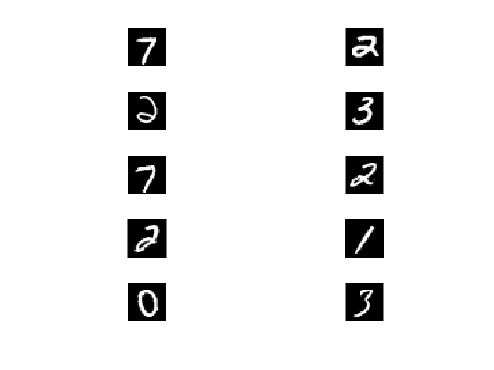

figure()
for i = 0:9
    subplot(5, 2, i + 1)
    imshow(reshaped_means(:, :, i + 1))
end

## separate the clusters

oldBucket = zeros(1, 10);
j = 0;
while j < 25
    % sort images into their respective classes
    class_buckets = zeros(784, 5000, 10);
    inBucket = zeros(1, 10);
    
    for i = 1:5000
        norm = sum((means - repmat(reshaped_imageTrain(:, i), 1, 10)) .^ 2);
        class = find(norm == min(norm));
        inBucket(1, class) = inBucket(1, class) + 1;
        class_buckets(:, i, class) = reshaped_imageTrain(:, i);
    end
    
    % calculate the means for each of the classes
    for i = 1:10
        means(:, i) = sum(class_buckets(:, :, i), 2) / inBucket(:, i);
    end

    % check if the cluster change is less than 0.2%
    if sum(abs(oldBucket - inBucket)) / (2 * 5000) < 0.002
        disp("broken")
        disp("number of iterations")
        disp(j + 1)
        break
    end
    disp(sum(abs(oldBucket - inBucket)) / (2 * 5000));
    oldBucket = inBucket;
    j = j + 1;
end

    0.5000

    0.0548

    0.0352

    0.0278

    0.0170

    0.0158

    0.0140

    0.0120

    0.0106

    0.0078

    0.0060

    0.0052

    0.0078

    0.0046

    0.0044

    0.0064

    0.0044

    0.0060

    0.0040

    0.0048

    0.0048

    0.0024

    0.0040

    0.0036

    0.0038



## display final means

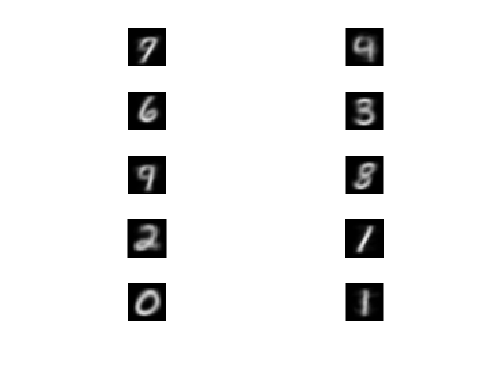

figure()
reshaped_means = reshape(means, 28, 28, 10);
for i = 0:9
    subplot(5, 2, i + 1)
    imshow(reshaped_means(:, :, i + 1))
end

## save file

save('current_means', 'reshaped_means')